# Stop function

**Description:** This file runs after stopping the execution on the simulink design. This code displays the received messages at the `Entity Terminator` block. This code also provides the following plots using the arrays in the `out` object:

## Received messages

disp('Received Messages:')

Received Messages:


disp(char(out.message_Rx.Data))

fontsize=22;
close all;

## Channel Collisions

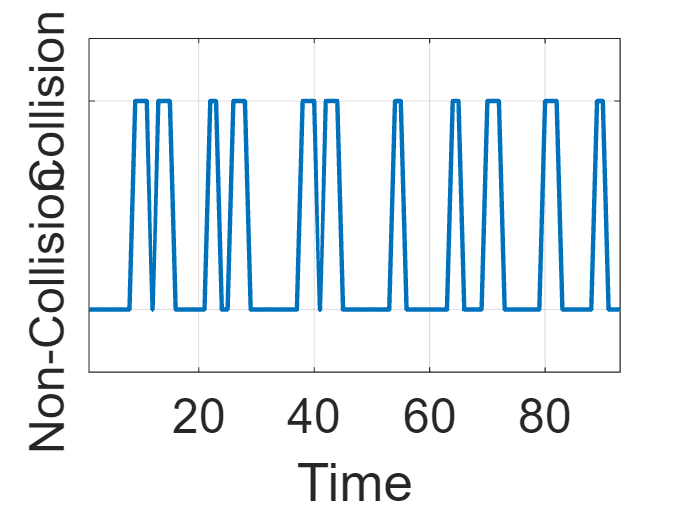

total_simulation=floor((out.SimulationClock.Data(end)));

GateStatus=zeros(1,total_simulation);

for i=2:2:length(out.TimeStampGate.Data)-1
    x1=out.TimeStampGate.Data(i);
    x2=out.TimeStampGate.Data(i+1);
    GateStatus(x1:x2)=ones(1,x2-x1+1);
end

plot(GateStatus,'LineWidth',2);
axis([1 total_simulation -0.3 1.3]);
set(gca, 'YTick', [0 1]);
set(gca, 'YTickLabel', {'Non-Collision','Collision'});
ytickangle(90);
xlabel('Time');
set(gca,'FontSize',fontsize);
grid on;

## Packet Losses

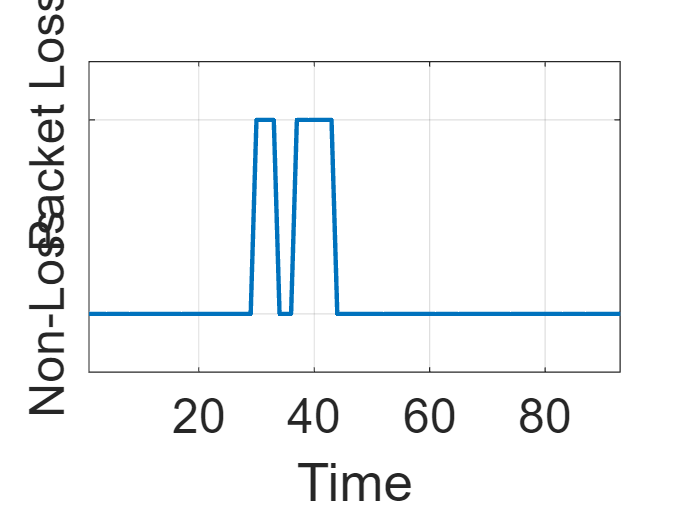

figure;

%finding the intervals where the gate block opens
PacketLoss=zeros(1,total_simulation);
for i=2:2:length(out.TimeStampPacketLoss.Data)-1
    x1=out.TimeStampPacketLoss.Data(i);
    x2=out.TimeStampPacketLoss.Data(i+1);
    PacketLoss(x1:x2)=ones(1,x2-x1+1);
end
%plotting results
plot(PacketLoss,'LineWidth',2);
axis([1 total_simulation -0.3 1.3]);
set(gca, 'YTick', [0 1]);
set(gca, 'YTickLabel', {'Non-Loss','Packet Loss'});
ytickangle(90);
xlabel('Time');
set(gca,'FontSize',fontsize);
grid on;

## Reception of packets

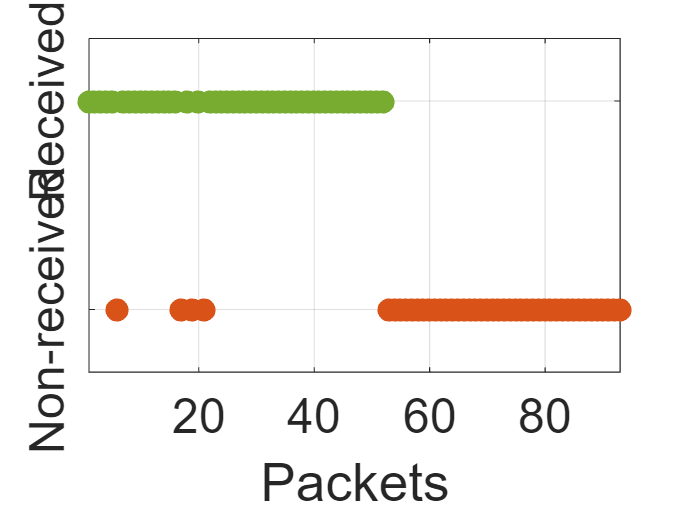

figure;
plot(out.MessageID.Data,ones(1,length(out.MessageID.Data)),'o',...
    'MarkerEdgeColor',"#77AC30",'MarkerFaceColor',"#77AC30",'MarkerSize',10); hold on;
axis([1 total_simulation -0.3 1.3]);
set(gca, 'YTick', [0 1]);
set(gca, 'YTickLabel', {'Non-received','Received'});
ytickangle(90);
xlabel('Packets');
set(gca,'FontSize',fontsize);
grid on;

%identifying the non-received packets
j=1;
for i=1:total_simulation
    if(sum(ismember(out.MessageID.Data,i))==0)
        packet_error(j)=i;
        j=j+1;
    end
end
plot(packet_error,zeros(1,length(packet_error)),'o',...
    'MarkerEdgeColor',"#D95319",'MarkerFaceColor',"#D95319",'MarkerSize',10);

## Transmitted and Received packets Timestamps

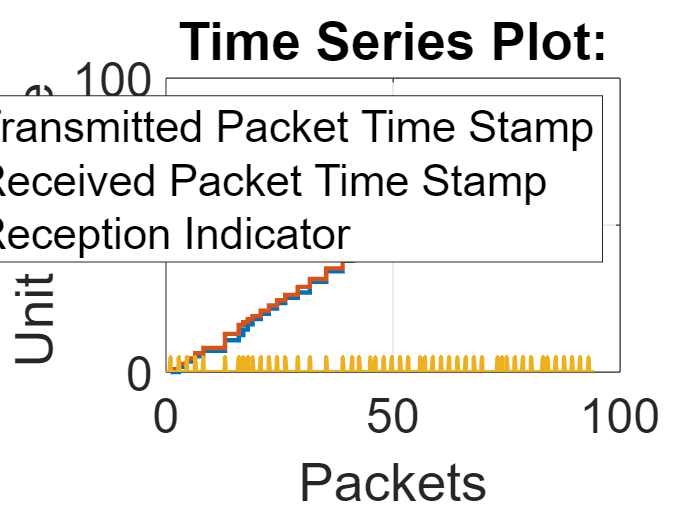

figure;
plot(out.TimeStampGeneration,'LineWidth',2);hold on; grid on;
plot(out.timeStampReceived,'LineWidth',2);
plot(out.packetIndicator.Time,out.packetIndicator.Data*5,'LineWidth',2);
ylabel('Unit of Time');
xlabel('Packets');
set(gca,'FontSize',fontsize);
legend('Transmitted Packet Time Stamp','Received Packet Time Stamp','Reception Indicator');

## AoI and Average AoI plot

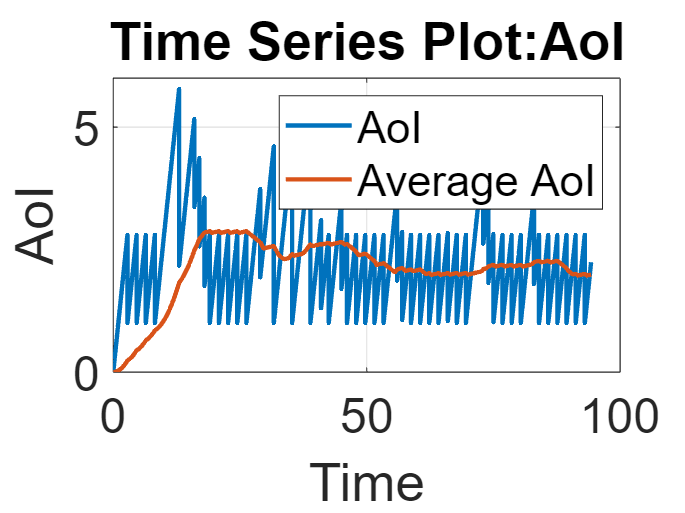

figure;
plot(out.AoI,'LineWidth',2);hold on; grid on;

plot(out.averageAoI,'LineWidth',2);
xlabel('Time');
set(gca,'FontSize',fontsize);
legend('AoI','Average AoI');

## PAoI plot

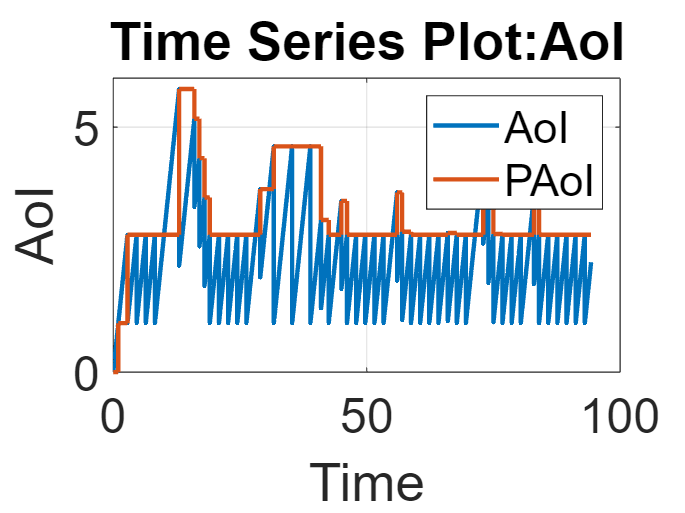

figure;
plot(out.AoI,'LineWidth',2);hold on; grid on;
plot(out.PAoI,'LineWidth',2);
xlabel('Time');
set(gca,'FontSize',fontsize);
legend('AoI','PAoI');